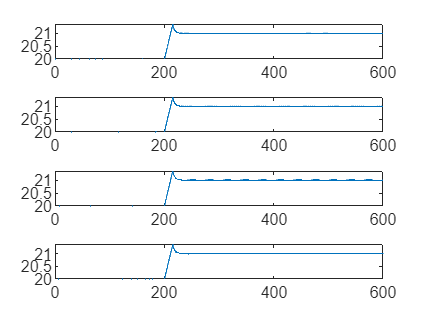

clc
clear
model.Parameters
Ks = zeros(1,3,4);
for i=1:4
    [T_wOP, q_OP, alpha, omega_s_OP, omega_OP] = control.calculateOperatingPoint(273.15+20,i);
    param.ctrl.alpha(i) = alpha;
    param.ctrl.T_wOP(i) = T_wOP;
    param.ctrl.T_aOP(i) = 273.15+20;
end
Ks(:,:,1) =[-0.0669, 0.3820, 0.0769];
Ks(:,:,2) = [-0.0390, 0.2228, 0.0449];
Ks(:,:,3) = [-0.0334, 0.1910, 0.0385];
Ks(:,:,4) =[-0.0557,0.3184, 0.0641];

simtime = 10*60;
for i=1:4
    x0 = [param.ctrl.T_wOP(i); param.ctrl.T_aOP(i); 0];
    u = [param.thermo.T_c; param.thermo.T_A; param.ctrl.Q(i)];    
    [t,x] = ode45(@(t,x)model.decoupledDynamics(t,x,u,i,Ks,param,200),[0 simtime],x0);
    restuls(i).time = t;
    restuls(i).Tw = x(:,1);
    restuls(i).Ta = x(:,2);
    restuls(i).T = x(:,3);
    % [dx,q] = model.decoupledDynamics(0,Ks,0,1)
end

figure()
tiledlayout('vertical')
for i=1:4
    nexttile
    plot(restuls(i).time,restuls(i).Ta-273.15)
end